(a) 

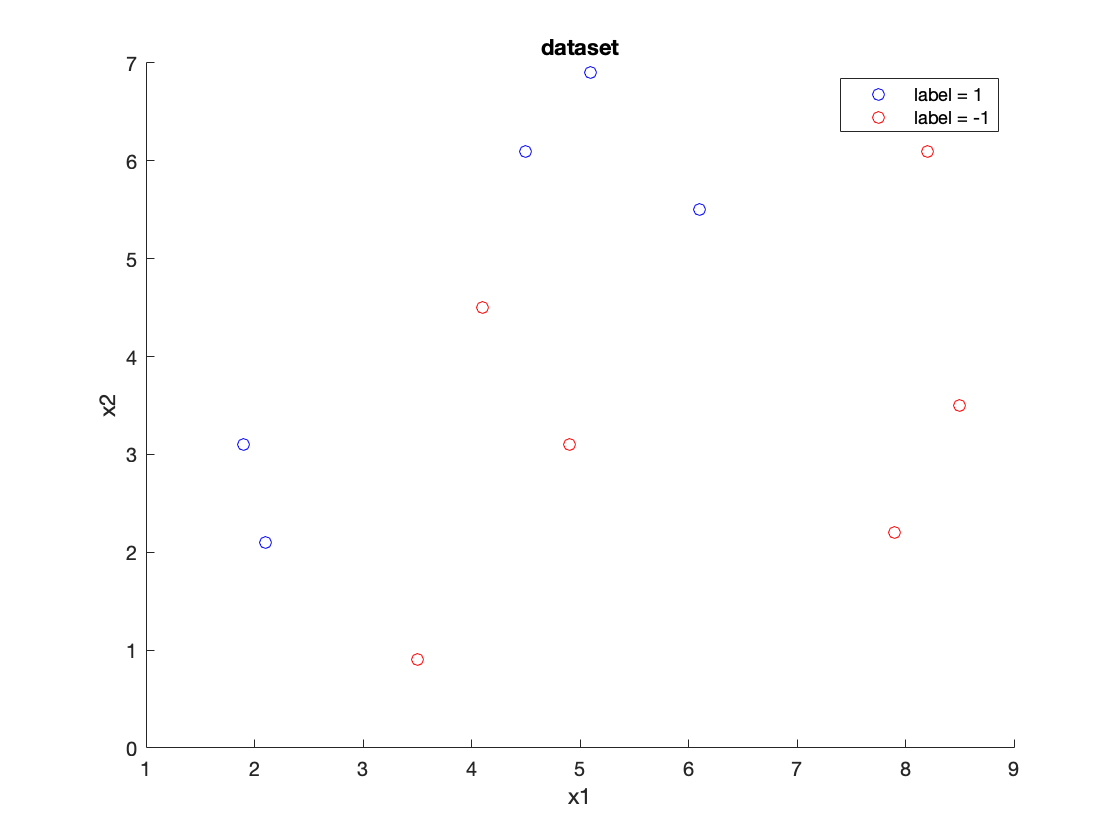

t = readtable('AdaBoost_data.csv');
x = t{:,1:2};
x1 = x(:,1);
x2 = x(:,2);
y = t{:,3};
figure(1);
hold on;
scatter(x1(y == 1), x2(y == 1), 'blue');
scatter(x1(y == -1), x2(y == -1), 'red');
xlabel('x1');
ylabel('x2');
legend('label = 1', 'label = -1');
title('dataset');

No, the data is not linearly separable. No, the data cannot be classified using a single layer decision tree.

(b)

i = [1 1 2];
s = [-1 -1 1];
t = [Inf Inf Inf];
N = length(y);
d = zeros(K + 1, N);
d(1,:) = 1 / N * ones(1, N);

a = zeros(K, 1);
for k = 1:3
    xi = x(:,i(k));
    ehatk = Inf;
    yhat = [];
    for tk = floor(min(xi)):ceil(max(xi))
        yh = sign(s(k) * (xi - tk));
        ek = sum(d(k, yh ~= y));
        if ek < ehatk
            ehatk = ek;
            t(k) = tk;
            yhat = yh;
        end
    end
    a(k) = 0.5 * log(1 / ehatk - 1);
    d(k+1,:) = d(k,:) .* exp(-a(k) * y .* yhat)';
    d(k+1,:) = d(k+1,:) / sum(d(k+1,:));
end
dvalues = array2table(d(1:3,:)', 'VariableNames',{'d0', 'd1', 'd2'})

dvalues = 11×3 table
       d0         d1          d2   
    ________    _______    ________

    0.090909     0.0625    0.038462
    0.090909     0.0625    0.038462
    0.090909    0.16667     0.10256
    0.090909     0.0625     0.16667
    0.090909     0.0625     0.16667
    0.090909    0.16667     0.10256
    0.090909     0.0625     0.16667
    0.090909    0.16667     0.10256
    0.090909     0.0625    0.038462
    0.090909     0.0625    0.038462
    0.090909     0.0625    0.038462


alpha = a'

alpha =     0.4904    0.7332    1.0184


tk = t

tk =      3     7     5


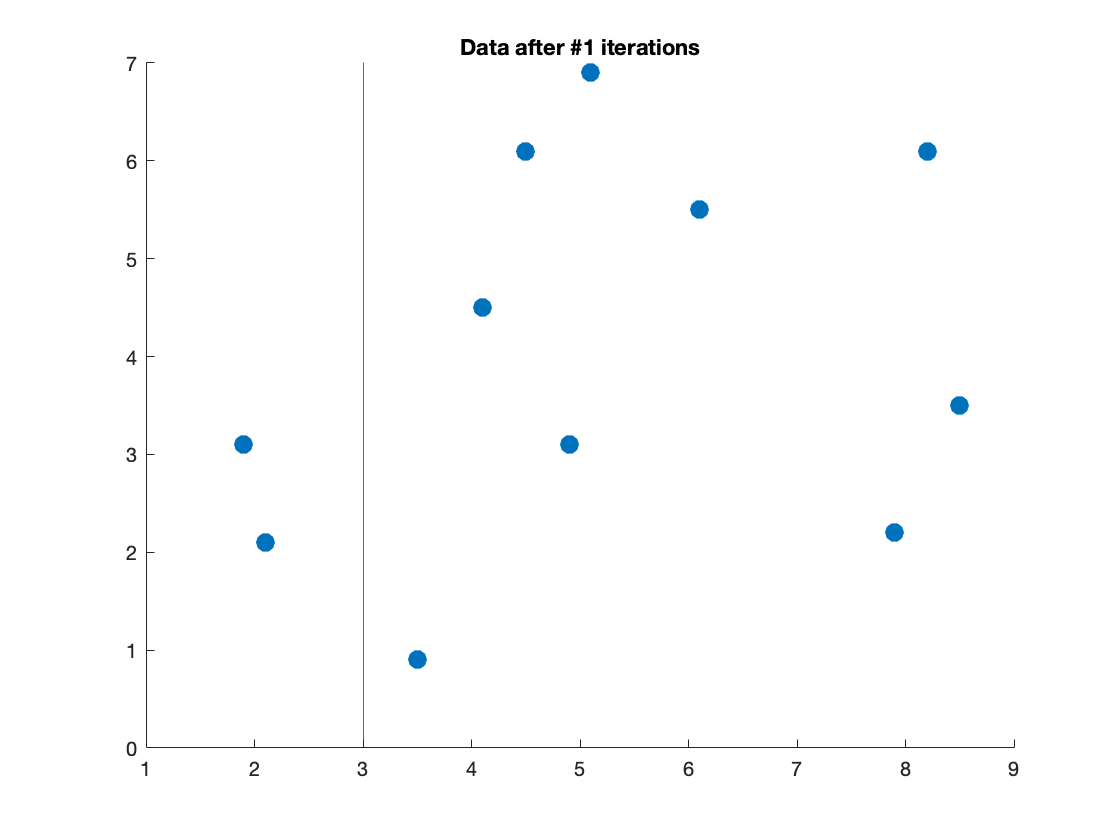

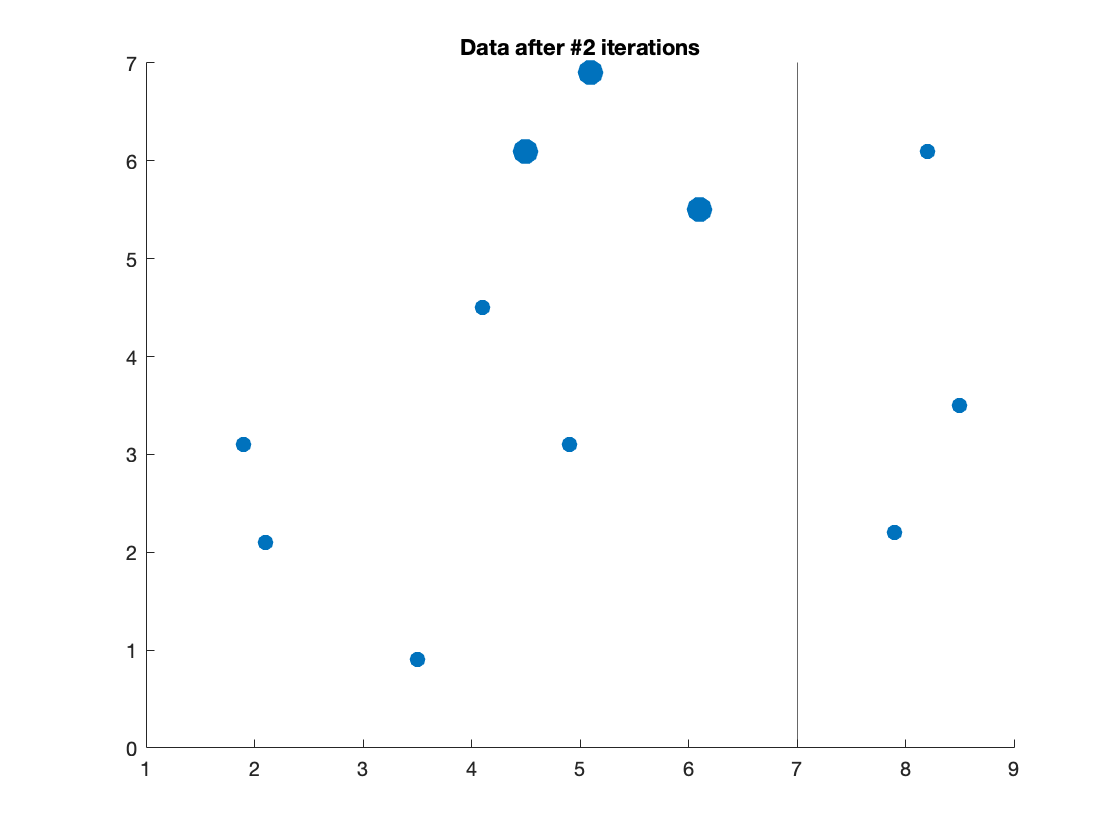

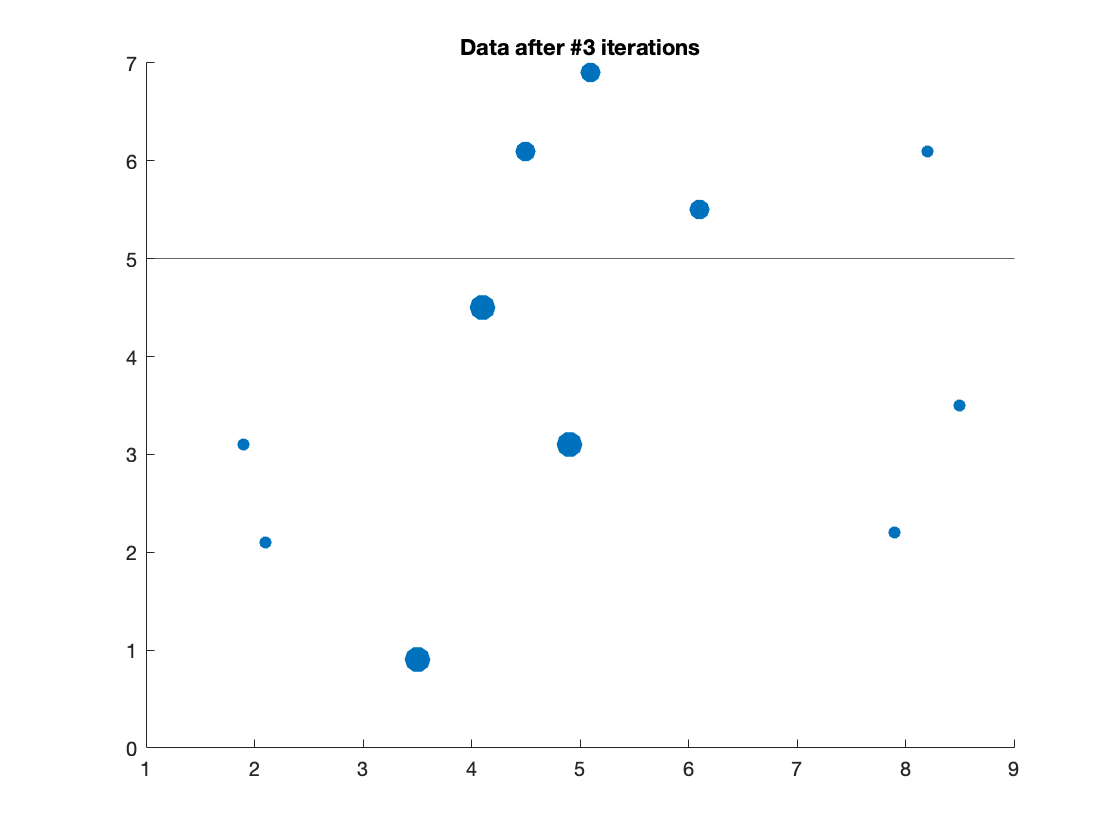

for k = 1:3
    figure(k+1);
    scatter(x1, x2, d(k,:) * 1000, 'filled');
    title(strcat('Data after #', int2str(k), ' iterations'));
    if i(k) == 1
        xline(t(k));
    else
        yline(t(k));
    end
end


f = zeros(size(y));
for k = 1:K
    f = f + a(k) * sign(s(k) * (x(:,i(k)) - t(k)));
end
final_combined_classifier = sign(f)'

final_combined_classifier =      1     1     1    -1    -1     1    -1     1    -1    -1    -1



acc = 100 * sum(f == y) / N

acc = 0